% Parámetros
m1 = 5;
m2 = 2;
L1 = 1;  
L2 = 0.6;
Fv = [4.5 0; 0 3.5];
g  = 9.8;
Tf = 30;

g2r = pi/180;
r2g = 180/pi;

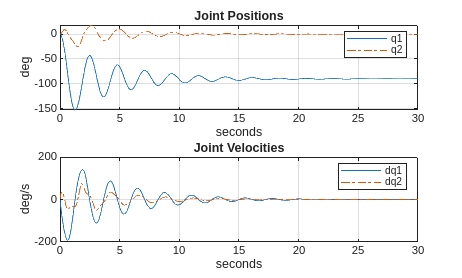

% Tau Iniciales Nulos
tau_zero = [0; 0]; 

% Condiciones iniciales nulas
x0_1 = [0; 0; 0; 0];            % [q1; q2; dq1; dq2]

repeticion(x0_1,tau_zero)

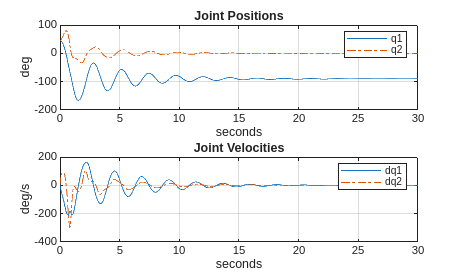

% Tau Iniciales Nulos
tau_zero = [0; 0]; 

% Condiciones iniciales a 45º
q0 = 45*g2r;
x0_2 = [q0; q0; 0; 0];            % [q1; q2; dq1; dq2]

repeticion(x0_2,tau_zero)

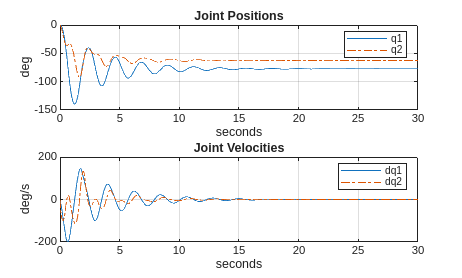

% Tau Iniciales No Nulos
tau_actuar = [6; -9]; 

repeticion(x0_1,tau_actuar)

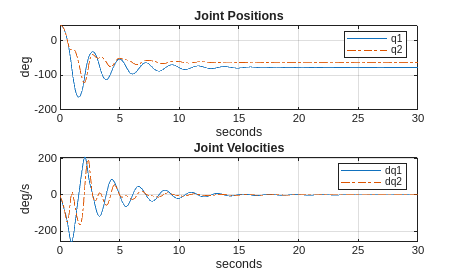

repeticion(x0_2,tau_actuar)

function repeticion(x0_i, tau)
    
    % Parámetros
    m1 = 5;
    m2 = 2;
    L1 = 1;  
    L2 = 0.6;
    Fv = [4.5 0; 0 3.5];
    g  = 9.8;
    Tf = 30;
    
    g2r = pi/180;
    r2g = 180/pi;
    
    % Ejecución del Problema
    [Ti,Qi] = ode45('rr_dynamics', [0 Tf], x0_i, [], m1, m2, L1, L2, Fv, tau, g);
    
    figure;

    subplot(2,1,1); % Positions
    plot(Ti,Qi(:,1)*r2g,'-',Ti,Qi(:,2)*r2g,'-.');
    legend('q1','q2');
    grid; title('Joint Positions'); xlabel('seconds'); ylabel('deg');
    
    subplot(2,1,2); % Joint velocities
    plot(Ti,Qi(:,3)*r2g,'-',Ti,Qi(:,4)*r2g,'-.');
    legend('dq1','dq2');
    grid; title('Joint Velocities'); xlabel('seconds'); ylabel('deg/s');

end